clc
clear
panda_model()
Theta = [pi/8; pi/8; pi/4; -pi/2; pi/8; pi/2; pi/6];
T1 = FK_SpaceForm(S, M, Theta)

T1 =     0.6245    0.4158   -0.6612    0.2548
    0.5680   -0.8228    0.0190    0.5613
   -0.5361   -0.3874   -0.7500    0.4709
         0         0         0    1.0000


robot = importrobot('Franka_Emika_Panda.urdf');

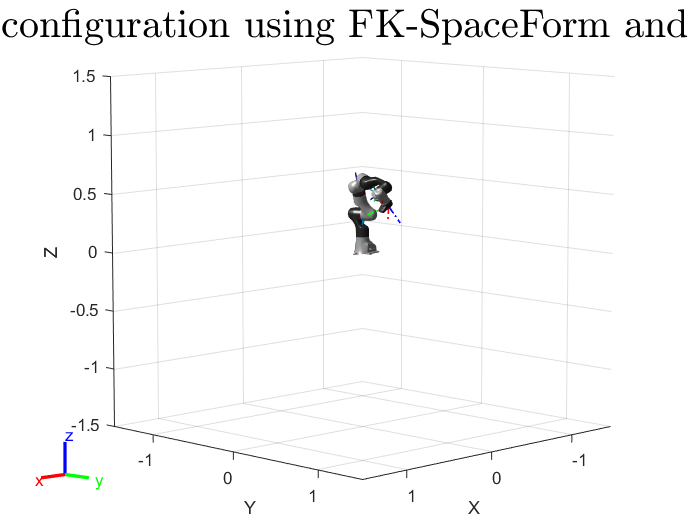

robot.DataFormat = 'column';
show(robot,Theta,'Visuals','on');
triad('Matrix',T1,'Scale',0.2,'LineWidth',1,'linestyle','-.');
title('End-effector configuration using FK-SpaceForm and Robot URDF.', 'FontSize',24, 'Interpreter','latex')


clc
clear
panda_model()
Theta = [pi/8; pi/8; pi/4; -pi/2; pi/8; pi/2; pi/6];
T2 = FK_BodyForm(B, M, Theta)

T2 =     0.6245    0.4158   -0.6612    0.2548
    0.5680   -0.8228    0.0190    0.5613
   -0.5361   -0.3874   -0.7500    0.4709
         0         0         0    1.0000


robot = importrobot('Franka_Emika_Panda.urdf');

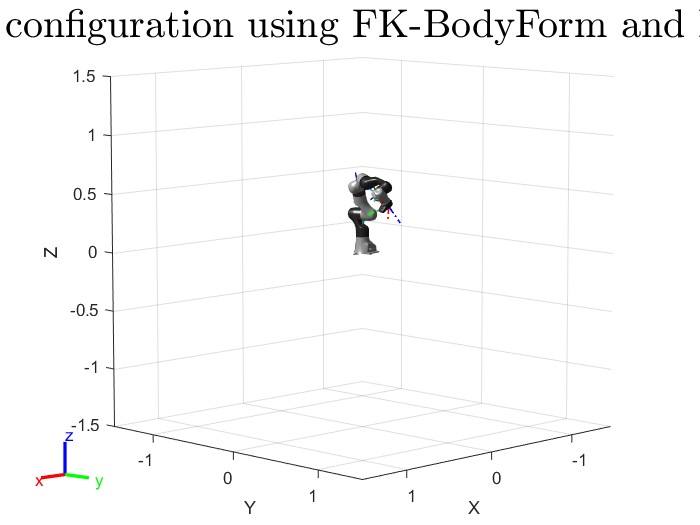

robot.DataFormat = 'column';
show(robot,Theta,'Visuals','on');
triad('Matrix',T2,'Scale',0.2,'LineWidth',1,'linestyle','-.');
title('End-effector configuration using FK-BodyForm and Robot URDF.', 'FontSize',24, 'Interpreter','latex')